# Sequence-based HH example

## Cleanup

clc
clear
close all


## Load required packages

addpath(genpath('extended\Domains\JSSP')); % Adds JSSP functionality
addpath(genpath('extended\Utils')); % Adds assorted utilities

## Load instances for testing

% ------ First set of training instances (5x5)
instanceDataset = '..\..\BaseInstances\JobShopScheduling\files\mat\Instances\E02\instanceDataset.mat';
load(instanceDataset);
trainInstances1 = num2cell(allInstances); % Stores instances as cell array

% ------ Second set of training instances (15x15)
instanceDataset = '..\..\BaseInstances\JobShopScheduling\files\mat\Instances\E01\instanceDataset.mat';
load(instanceDataset);
trainInstances2 = num2cell(allInstances); % Stores as cell array

## First HH

targetProblem = "job shop scheduling";
nbRules = 3;
selectedFeatures = 3:4;
propsHH = struct('nbRules',nbRules,'targetProblem', targetProblem,'selectedFeatures',selectedFeatures);
HH1 = ruleBasedSelectionHH(propsHH);
disp(HH1)

Displaying information about the New HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time taken:	NaN
	Evaluations taken:	NaN
	Iterations performed:	NaN
	Status of stop criteria:
   NaN

Model-specific information:
	Number of rules:	3
	Usable features:	2 (toDo: Include here the ID of each feature, in order)
	Usable solvers:	4 (toDo: Include here the ID of each solver, in order)
	Current model:
    0.6948    0.0344    4.0000
    0.3171    0.4387    4.0000
    0.9502    0.3816    1.0000



## Second HH

nbRules = 4;
selectedFeatures = 3:5;
propsHH = struct('nbRules',nbRules,'targetProblem', targetProblem,'selectedFeatures',selectedFeatures);
HH2 = ruleBasedSelectionHH(propsHH);
disp(HH2)

Displaying information about the New HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time taken:	NaN
	Evaluations taken:	NaN
	Iterations performed:	NaN
	Status of stop criteria:
   NaN

Model-specific information:
	Number of rules:	4
	Usable features:	3 (toDo: Include here the ID of each feature, in order)
	Usable solvers:	4 (toDo: Include here the ID of each solver, in order)
	Current model:
    0.4898    0.7547    0.1626    2.0000
    0.4456    0.2760    0.1190    3.0000
    0.6463    0.6797    0.4984    1.0000
    0.7094    0.6551    0.9597    4.0000



## Training

% Instance assignment:
HH1.trainingInstances = trainInstances1;
HH2.trainingInstances = trainInstances1;

% Parameters:
trainingMethod = 'UPSO';
maxIter = 50;
populationSize = 30;
selfConf = 2.1;
globalConf = 2.1;
unifyFactor = 0.5;
visualMode = false;
trainingParams = struct('maxIter',maxIter,'populationSize',populationSize,'selfConf',selfConf,'globalConf',globalConf,'unifyFactor',unifyFactor,'visualMode',visualMode);

% Process:
HH1.train(trainingMethod, trainingParams);


[  09:27:23] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 30
              maxIter: 50
          maxStagIter: 50
             selfConf: 2.1000
           globalConf: 2.1000
          unifyFactor: 0.5000
      numberVariables: 9
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.2000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 1.425e+04
         ... Initialisation completed!

[Step     2

HH2.train(trainingMethod, trainingParams);


[  09:45:25] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 30
              maxIter: 50
          maxStagIter: 50
             selfConf: 2.1000
           globalConf: 2.1000
          unifyFactor: 0.5000
      numberVariables: 16
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.2000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 1.395e+04
         ... Initialisation completed!

[Step     

## Testing

## Comparison

% Model display
disp(HH1)

Displaying information about the Trained HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     UPSO
	Number of instances: 30 (training) | 0 (testing)
	Parameters:
        visualMode: 0
       verboseMode: 1
    populationSize: 30
           maxIter: 50
       maxStagIter: 50
          selfConf: 2.1000
        globalConf: 2.1000
       unifyFactor: 0.5000

	Performance achieved:	14184.00
	Time taken:	1056.18
	Evaluations taken:	1550
	Iterations performed:	50
	Status of stop criteria:
       iterationFlag: 1
    fitnessLimitFlag: 0
      stagWindowFlag: 0
        stagStatFlag: 0

Model-specific information:
	Number of rules:	3
	Usable features:	2 (toDo: Include here the ID of each feature, in order)
	Usable solvers:	4 (toDo: Include here the ID of each solver, in order)
	Current model:
    1.0000    0.7289    4.0000
         0    0.8990    3.0000
    0.9417    0.5983    4.0000



disp(HH2)

Displaying information about the Trained HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     UPSO
	Number of instances: 30 (training) | 0 (testing)
	Parameters:
        visualMode: 0
       verboseMode: 1
    populationSize: 30
           maxIter: 50
       maxStagIter: 50
          selfConf: 2.1000
        globalConf: 2.1000
       unifyFactor: 0.5000

	Performance achieved:	13872.00
	Time taken:	1004.95
	Evaluations taken:	1550
	Iterations performed:	50
	Status of stop criteria:
       iterationFlag: 1
    fitnessLimitFlag: 0
      stagWindowFlag: 0
        stagStatFlag: 0

Model-specific information:
	Number of rules:	4
	Usable features:	3 (toDo: Include here the ID of each feature, in order)
	Usable solvers:	4 (toDo: Include here the ID of each solver, in order)
	Current model:
    1.0000    0.7028    0.8886    1.0000
    0.7203    0.0902    0.3738    3.0000
    0.4744    0.2951    0.4944    2.0000
    0.1258    0.3674    0.3246    3.0

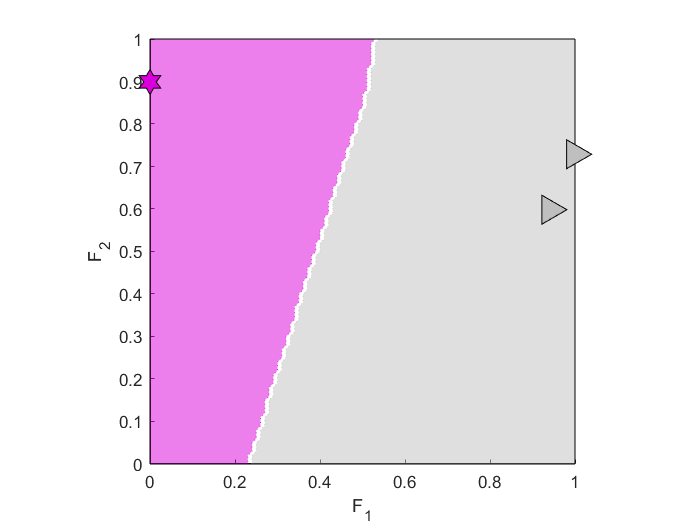


% Zones of influence
% --- Parameters:
points             = 0:0.01:1;
selectedFeatures   = 1:2;
useEuclid          = true; % Use Euclidean distance
doRules            = true; % Plot rules along with zones
% --- Plots:
HH1.plotZones(points, useEuclid, selectedFeatures, doRules)

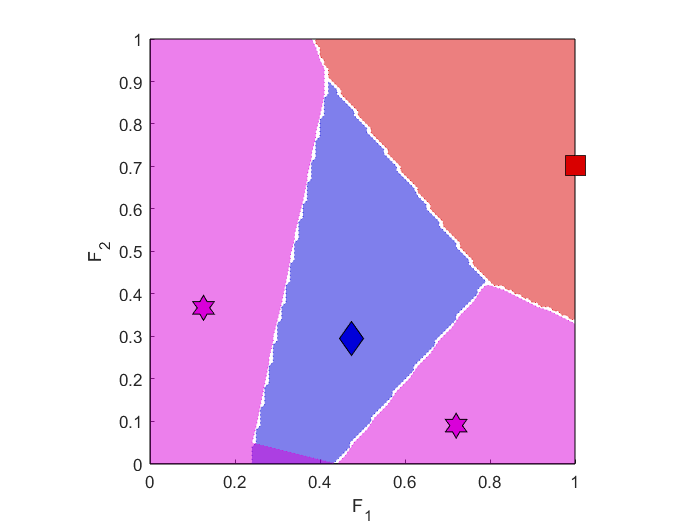

HH2.plotZones(points, useEuclid, selectedFeatures, doRules)

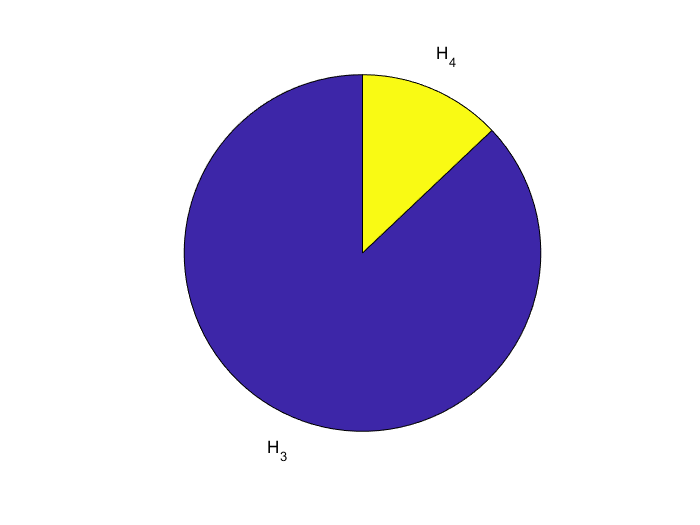

% Solver usage on the training set
% --- Double check that adequate data are used
HH1.solveInstanceSet(trainInstances1);
HH2.solveInstanceSet(trainInstances1);
% --- Actual plots
figure, [~, fV1]=HH1.plotSolverUsageDistributionMulti(1:30, true);

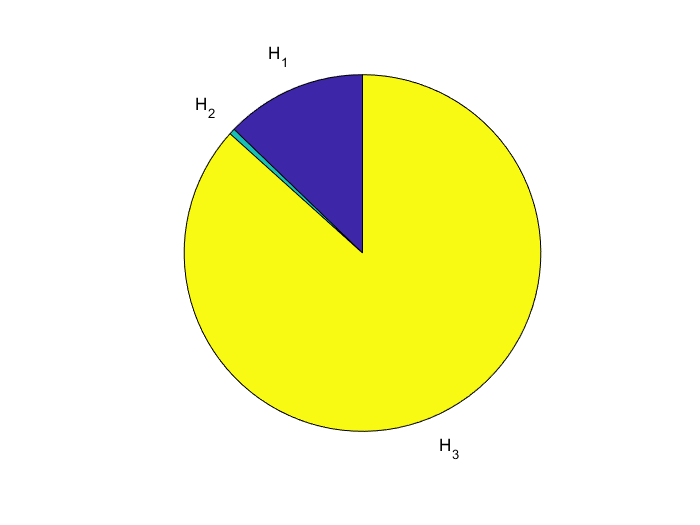

figure, [~, fV2]=HH2.plotSolverUsageDistributionMulti(1:30, true);

ans =   Axes with properties:

             XLim: [332.5000 717.5000]
             YLim: [0 14]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


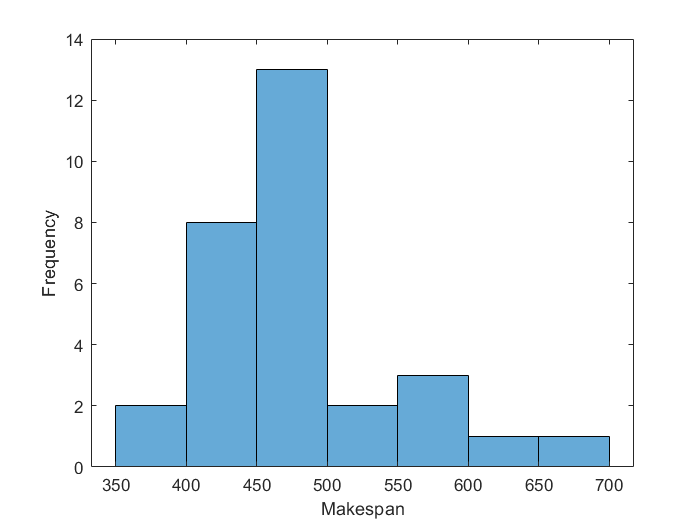


% Makespan distribution of final solutions per instance
figure(); HH1.plotStepSolutionDistribution('end')

ans =   Axes with properties:

             XLim: [337.5000 612.5000]
             YLim: [0 12]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


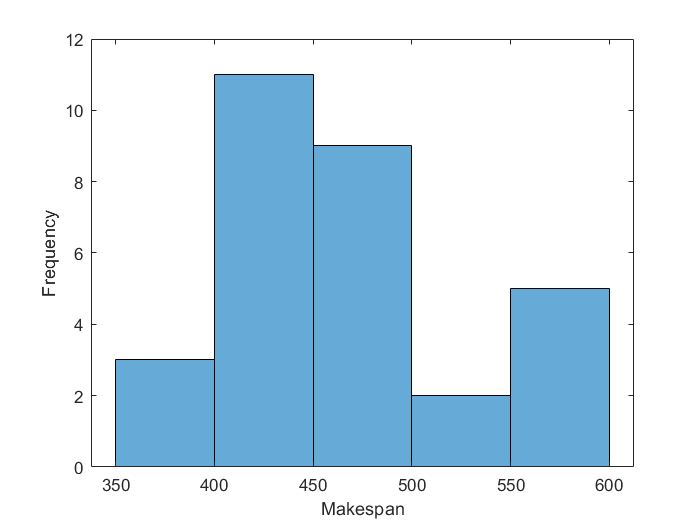

figure(); HH2.plotStepSolutionDistribution('end')

## Save backup data

save('HHComparison.mat')